# Homework 1 (Assignment 2 online)

## Details

Author - Davis Vaughan

Date    - 2017-09-07

HW      - 01

## Setup

%%% Reproducible seed
rng(123);

%%% Parameters
M       = mod(800808804, 25); % Assignment #
N       = 10000;              % Sim number
r       = 0.02 + 0.002 * M;   % Risk free rate
sigma   = 0.25 + 0.005 * M;   % Volatility
T       = 0.5;                % Length
dt      = 1/12;               % Time step
t_total = T / dt;             % Total time steps
s_0     = 100;                % Stock price time 0

## 1.1 a - Exact simulation

Black Scholes stock price - exact


$$s_t = s_0 * e^{(r - \frac{1}{2} * \sigma ^ 2) t + \sigma * W_t}$$


% ~N(0,1) random matrix
z = [zeros(N, 1) randn(N, t_total)];

% dW matrix
dW = sqrt(dt) * z;

% rowwise cumulative sum of dW to get W at each time step
W = cumsum(dW, 2);

% 10k sim stock prices for 6 steps each
s_t = s_0 * exp((r-1/2 * sigma^2) * (0:dt:T) + sigma * W)

s_t =   100.0000  106.0635  108.8994  113.3095  126.8332  136.3646  124.9178
  100.0000   95.3268  109.0884  120.7181  124.2624  143.0030  141.9682
  100.0000   92.1849   97.8680   94.7270   93.6786   84.8309   79.5844
  100.0000  101.5107  112.0572  124.3816  106.4230  115.7596  138.6575
  100.0000  105.2701   93.9084   93.7112   85.8521   94.7556   84.8290
  100.0000   97.4415  102.4830  100.9896   97.8820   97.5860   96.4392
  100.0000  110.8821  116.5875  112.1505  107.9082  104.2905  113.7428
  100.0000  104.8889   91.1611   90.3554   93.8816   91.8872   97.0250
  100.0000   99.6734   98.0620  110.3868  101.5576   95.5643  105.4260
  100.0000   97.6575   92.6558   98.3358   93.7895   98.9507  109.9458


## 1.1 b - Euler scheme

Black Scholes Euler scheme


$$s_{t + dt} = s_t + (r * s_t * dt) + (\sigma * s_t * (W_{t + dt} - W_t))$$



$$s_{t + dt} = s_t + (r * s_t * dt) + (\sigma * s_t * \sqrt{dt} * Z)$$


% Set up s_t matrix to fill. Initialize to s_0
s_t_euler = nan(N, t_total + 1);
s_t_euler(:, 1) = s_0;

% Fill the columns (time steps). 1 row per path
for(i = 1:t_total)
    s_t_euler(:, i+1) =  s_t_euler(:, i) + r * s_t_euler(:, i) * dt + sigma * s_t_euler(:, i) * sqrt(dt) .* z(:, i+1);
end

s_t_euler

s_t_euler =   100.0000  106.1905  109.3151  113.9868  127.1850  136.7870  125.2095
  100.0000   95.5179  108.6883  120.0285  123.8664  141.6422  141.0437
  100.0000   92.1664   97.9600   95.0621   94.2929   85.2245   80.0424
  100.0000  101.8032  112.1752  124.2208  105.2280  114.3967  135.3918
  100.0000  105.4397   93.7178   93.8054   85.8737   94.6081   84.4259
  100.0000   97.7120  102.9378  101.7394   98.8686   98.8694   98.0010
  100.0000  110.6335  116.5205  112.3534  108.3622  104.9962  114.4246
  100.0000  105.0769   90.6566   90.1272   93.8513   92.1211   97.4130
  100.0000   99.9766   98.6508  110.6298  101.7432   95.8636  105.5695
  100.0000   97.9333   93.0820   98.9028   94.5217   99.8722  110.6987


## 1.1 Extra requirements

% Mean squared discretization error
mse = mean((s_t - s_t_euler) .^2);
mse(:, 7)

ans = 1.1669

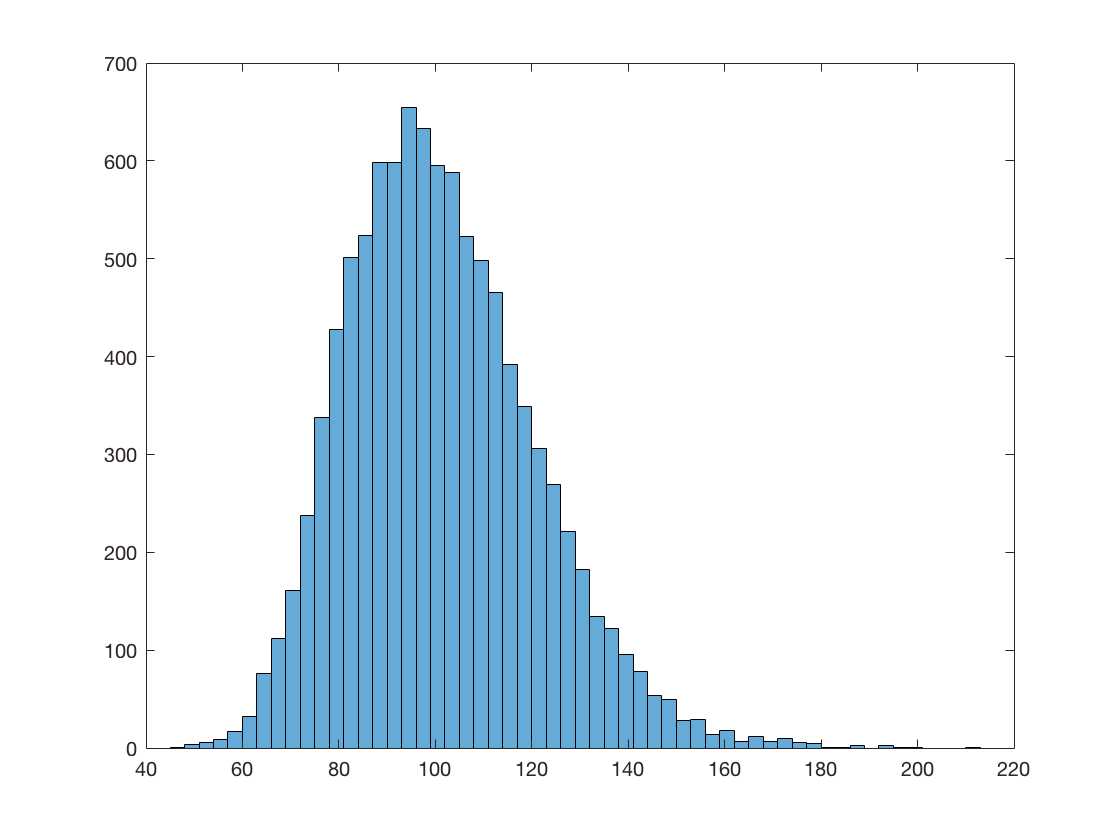


% Histogram of lognormal s_T for case a
s_T = s_t(:, t_total + 1);
histogram(s_T)

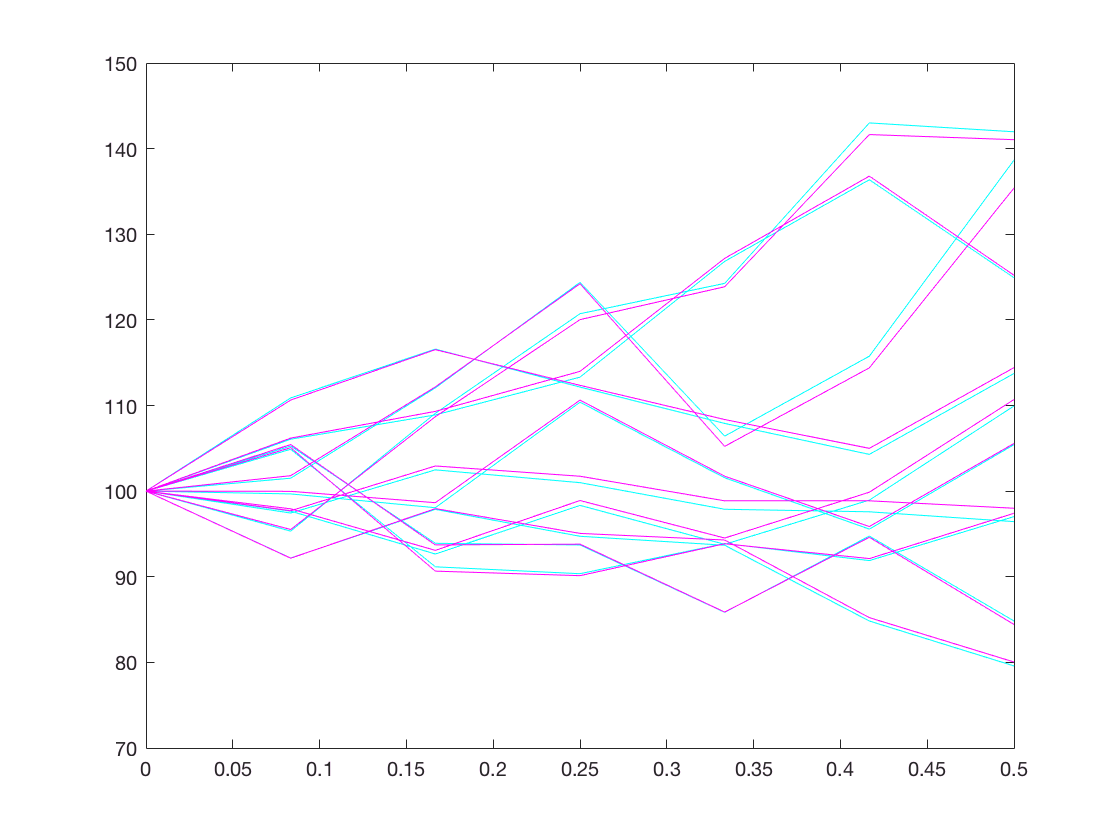


% Plot first 10 paths of each with same seed
% Cyan is exact
% Magenta is Euler discretization
plot(0:dt:T, s_t(1:10,  :),      'c', ...
     0:dt:T, s_t_euler(1:10, :), 'm')

## Discussion:

The discretization error is definitely noticeable in the plot. It looks like the farther

away we get from time 0, the more discretization error is introduced. 

Decreasing dt would likely help this. Otherwise, they look similar and look like what

we would expect from this kind of stock price simulation.

## 1.2 Option price based on 1.1a compared to Black Scholes

% At the money, so K = 100
k = 100;

% European Call option prices at time 0
c_0 = exp(-r * T) * max(0, s_T - k);

% Average call option price
c_hat_0 = mean(c_0)

c_hat_0 = 8.2636


% Black scholes european call option price
d_1 = (log(s_0 / k) + (r + sigma^2 / 2) * T ) / (sigma * sqrt(T));
d_2 = d_1 - sigma * sqrt(T);

bs_c_0 = s_0 * normcdf(d_1) - k * exp(-r * T) * normcdf(d_2)

bs_c_0 = 8.2675


% Out of curiousity, price from 1.1b
c_0_euler = exp(-r * T) * max(0, s_t_euler(:, t_total + 1) - k);
c_hat_0_euler = mean(c_0_euler)

c_hat_0_euler = 8.2753

## Discussion

Neither of the models gave the exact same option price as black scholes, but the exact method got very close. 

Increasing the number of paths and decreasing the time step would likely get us very close to the black scholes value.